# Fernando Henriques Neto RA: 18.00931-0

## 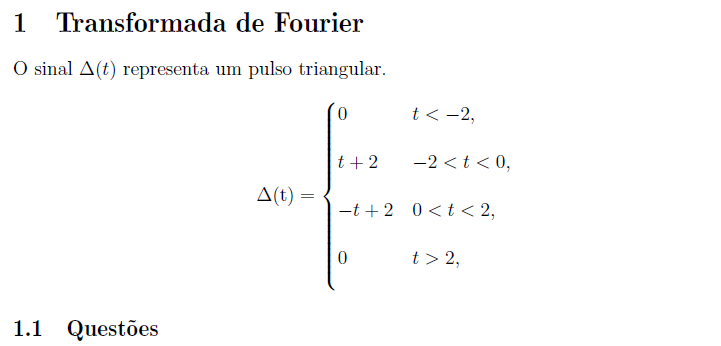

### 1.	Determine analiticamente transformada de Fourier ∆(ω).

### 2. Determine o termo Dn para o caso do sinal ∆(t) ser repetido a cada To = 4 segundos.

### $To=4$ [s]

#### $Wo=\ \frac{2\pi }{To}\ =\frac{2\pi }{4}=\frac{\pi }{2}$ [rad/s]

### 
$$Dn=\ \frac{1}{4}\int_{-2}^0 t\ldotp e^{-j\ldotp \;n\ldotp \;\frac{\;\pi }{2}\ldotp \ t} dt+\ \frac{1}{4}\int_{-2}^0 2\ldotp e^{-j\ldotp \;n\ldotp \;\frac{\;\pi \;}{2}\ldotp \;t} dt+\frac{1}{4}\int_0^2 -t\ldotp e^{-j\ldotp \;n\ldotp \;\frac{\pi \;}{2}\ldotp \;t} dt+\ \frac{1}{4}\int_0^2 2\ldotp e^{-j\ldotp \;n\ldotp \;\frac{\pi \;}{2}\ldotp \;t} dt=-\frac{e^{-jn\pi } +e^{jn\pi \ } -2}{\pi^2 n^2 }\ =\;\ \frac{-2\;\ldotp \textrm{Cos}\left(\pi \ldotp n\right)+2}{\pi^2 n^2 }\;\;$$


#### 3. Elabore um código Matlab/Octave que veriﬁque se a expressão de Dn obtida no item anterior está correta. Compare com o esperado.

## Boas práticas

clc;                                  % limpa a tela
clear all;                            % limpa as variáveis
close all;                            % fecha as figuras

## Declaração de Variáveis 

syms t n;
ti = -2;
tf =  2;
To = 4;                               % Período
Wo = (2*pi)/4;                      % Frequência Fundammental

## Declaração de Funções

g1 = @(t) t+2;                        % Função g1
g2 = @(t) -t+2;                       % Função g2

## Cálculo de Dn Simbólico


F1 = (1/To)*int(g1*exp(-j*n*Wo*t),t,ti,0);     % Cálculo de g(t+2)
F2 = (1/To)*int(g2*exp(-j*n*Wo*t),t,0,tf);     % Cálculo de g(-t+2)

Dn = F1 + F2                          % Dn

$$Dn = \frac{1}{n^{2}\,\pi^{2}}-\frac{\mathrm{i}}{n\,\pi }+\frac{1-{\mathrm{e}}^{\pi \,n\,\mathrm{i}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}-\frac{{\mathrm{e}}^{-\pi \,n\,\mathrm{i}}}{n^{2}\,\pi^{2}}$$

## Cálculo de Dn Numérico 

nPontos = 10;
n = [-nPontos:1:nPontos];
Dn = eval(Dn);

## Correção de Dn devido ao Valor Médio

Do = (1/To)*int(g1,t,ti,0) + (1/To)*int(g2,t,0,tf);
Do = eval(Do);                                        % Corrigindo o valor médio

## Gráfico da Função em função da Frequência

f = n*((1/To));           % eixo x
Dn(nPontos+1) = Do;        % eixo y

figure(1) 
stem(f,abs(Dn));
title('Serie de Fourier do sinal g(t)');
xlabel('Frequencia em Hz');
ylabel('Amplitude em  volts')
hold

Current plot held


## Gráfico da Função G(t) Estudada  em função do Tempo

ts = To/nPontos;
tempo = linspace(0,3*To,nPontos);
aux = 0;

for k = 1:length(n)
    aux = aux + Dn(k)*exp(j*n(k)*Wo*tempo);
end
gt = aux

gt =    1.9596 - 0.0000i   0.6703 - 0.0000i   0.6703 - 0.0000i   1.9596 + 0.0000i   0.6703 - 0.0000i   0.6703 - 0.0000i   1.9596 - 0.0000i   0.6703 - 0.0000i   0.6703 + 0.0000i   1.9596 + 0.0000i


figure(2)
plot(tempo,gt,'linewidth',3); 

title('Sinal g(t)');
grid();
xlabel('Tempo em segundos');
ylabel('Amplitude em  volts');
hold

Current plot held


## 4. Utilizando o mesmo cóodigo determine a Banda necessária para que tenhamos 95 %da potˆencia do sinal.

aux = 0;
DnAbs = abs(Dn);
PT =  DnAbs*DnAbs'

PT = 1.3333


for k = 1:length(n)
    aux = aux + 2*(DnAbs(k)^2);
    if (aux/PT) > 0.95
        Banda = k
        break
    end
end

Banda = 11

## 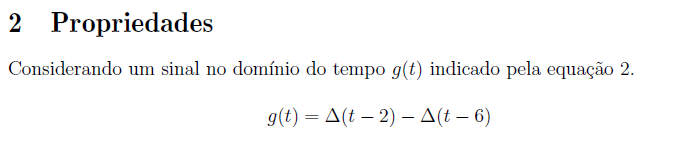

## 2.1 Questões

## 1.	Determine a transformada de Fourier utilizando a propriedade do deslocamento no tempo - to.

### 
$$\begin{array}{l}
Dn_1 =Dn_{\;} \left(\textrm{Questão}\;1\right)\\
Dn_2 =-Dn_1 \ldotp e^{-j\ldotp 2\ldotp n{\ldotp W}_0 } \\
Dn_{\textrm{Total}} =Dn_1 -Dn_2 =Dn_1 -Dn_1 \ldotp e^{-j\ldotp 2\ldotp n{\ldotp W}_0 } \;\\
Dn_{\textrm{Total}} =Dn_1 \ldotp \left(1-e^{-j\ldotp 2\ldotp n{\ldotp W}_0 } \right)
\end{array}$$


## 2.	Determine o termo Dn para o caso do sinal ∆(t) ser repetido a cada T0 = 8 segundos.

### 
$$\begin{array}{l}
\textrm{Para}\;\textrm{To}=8:\\
\textrm{Wo}=\frac{2\pi }{\textrm{To}}=\frac{\pi }{4}\\
Dn_{\textrm{Total}} =\frac{-\textrm{Cos}\left(\pi \ldotp n\right)+1}{4\pi ²\ldotp \textrm{n²}}\ldotp \left(1-e^{-j\ldotp 2\ldotp n{\ldotp W}_0 } \right)\\
Dn_{\textrm{Total}} =\frac{-\textrm{Cos}\left(\pi \ldotp n\right)+1}{4\pi ²\ldotp \textrm{n²}}\ldotp \left(1-e^{-j\ldotp 2\ldotp n\ldotp \frac{\pi }{4}} \right)
\end{array}$$


## 3.	Elabore um código Matlab/Octave que veriﬁque se a expressão de Dn obtida no item anterior está correta. Compare com o esperado.

## Boas práticas

clc;                                  % limpa a tela
clear all;                            % limpa as variáveis
close all;                            % fecha as figuras

## Declaração de Variáveis 

To = 8;
ti = 0;
t1 = 2;
t2 = 6;
tf = 8;   

## Declaração de Funções

gp = @(t) t;             
gn = @(t) -t+4;
gp1 = @(t) t-8;

## Primeiro Pulso

N  = 1000;               % harmônicas
fo = 1/To;               % frequência em Hz
wo = 2*pi*fo;            % frequência fundamental angular
                          
n  = [-N:1:N];            
f  = n*fo;               % vetor

M = 1000;
Ts = To/M;
tempo = [0:Ts:To];  % Tempo de simulação de um período do sinal g(t)

## Fourier Simbolicamente

syms n t

Dn = inv(To)*int(gp*exp(-j*n*wo*t),t,ti,t1) + inv(To)*int(gn*exp(-j*n*wo*t),t,t1,t2) + inv(To)*int(gp1*exp(-j*n*wo*t),t,t2,tf);
D_o = inv(To)*int(gp,t,ti,t1) + inv(To)*int(gn,t,t1,t2) + inv(To)*int(gp1,t,t2,tf);

## Dn numericamente

n=[-N:1:N];
 
Dn = eval(Dn);
D_o = eval(D_o);     % Corrigindo o valor médio devido a indeterminação
Dn(N+1) = D_o;       % Subistituindo no vetor


## Gráfico da Função em função da Frequência 

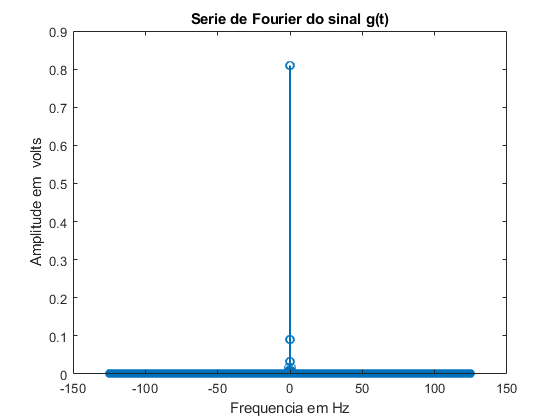

figure(3)
stem(f,abs(Dn));
title('Serie de Fourier do sinal g(t)');
xlabel('Frequencia em Hz');
ylabel('Amplitude em  volts')

## Gráfico da Função G(t) Estudada  em função do Tempo

n=[-N:1:N];
aux  = 0; 

for k = 0 : 2*N     
  aux = aux + Dn(k+1)*exp(j*n(k+1)*wo*tempo);  
end
gt = aux;

figure(4)
plot(tempo,gt,'linewidth',3); 

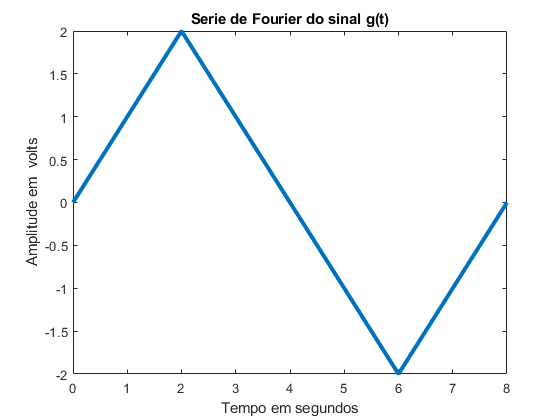

title('Serie de Fourier do sinal g(t)');
xlabel('Tempo em segundos');
ylabel('Amplitude em  volts');

## Utilizando o mesmo código determine a Banda necessária para que tenhamos 95 %da potência do sinal.

aux = 0;
DnAbs = abs(Dn);
PT =  DnAbs*DnAbs'

PT = 1.3333


for k = 1:length(n)
    aux = aux + 2*(DnAbs(k)^2);
    if (aux/PT) > 0.95
        Banda = k
        break
    end
end

Banda = 1000